# Train a *k*-Nearest Neighbor Classifier Using the Minkowski Metric

Load Fisher's iris data set.

load fisheriris
X = meas;
Y = species;

`X` is a numeric matrix that contains four petal measurements for 150 irises.  `Y` is a cell array of character vectors that contains the corresponding iris species.

Train a 3-nearest neighbors classifier using the Minkowski metric. To use the Minkowski metric, you must use an exhaustive searcher. It is good practice to standardize noncategorical predictor data.

Mdl = fitcknn(X,Y,'NumNeighbors',3,...
    'NSMethod','exhaustive','Distance','minkowski',...
    'Standardize',1);

`Mdl` is a `ClassificationKNN` classifier.

You can examine the properties of `Mdl` by double-clicking `Mdl` in the Workspace window. This opens the Variable Editor.

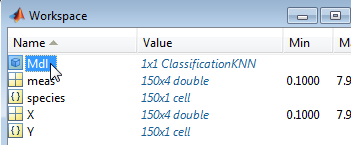

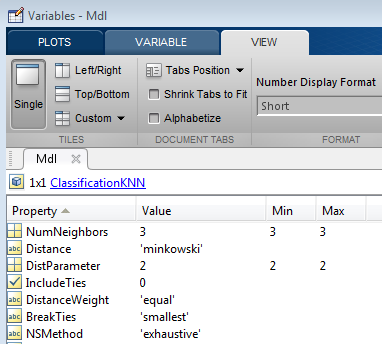

*Copyright 2012 The MathWorks, Inc.*